In the theory of vibrations of a circular drum, the displacement of the drumhead can be expressed in terms of pure harmonic modes,


$$J_m(\omega_{k,m} r) \cos(m\theta) \cos(c \omega_{k,m} t),$$


where $(r,\theta)$ are polar coordinates, $0\le r\le 1$, $t$ is time, $m$ is a positive integer, $c$ is a material parameter, and $J_m$ is a *Bessel function of the first kind*. The quantity $\omega_{k,m}$ is a resonant frequency and is a positive root of the equation


$$J_m(\omega_{k,m}) = 0,$$


which states that the drumhead is clamped around the rim. Tabulating approximations to the zeros of Bessel functions has occupied countless mathematician-hours throughout the centuries. 

Too bad they didn't have MATLAB back in the day. Bessel functions are built in.

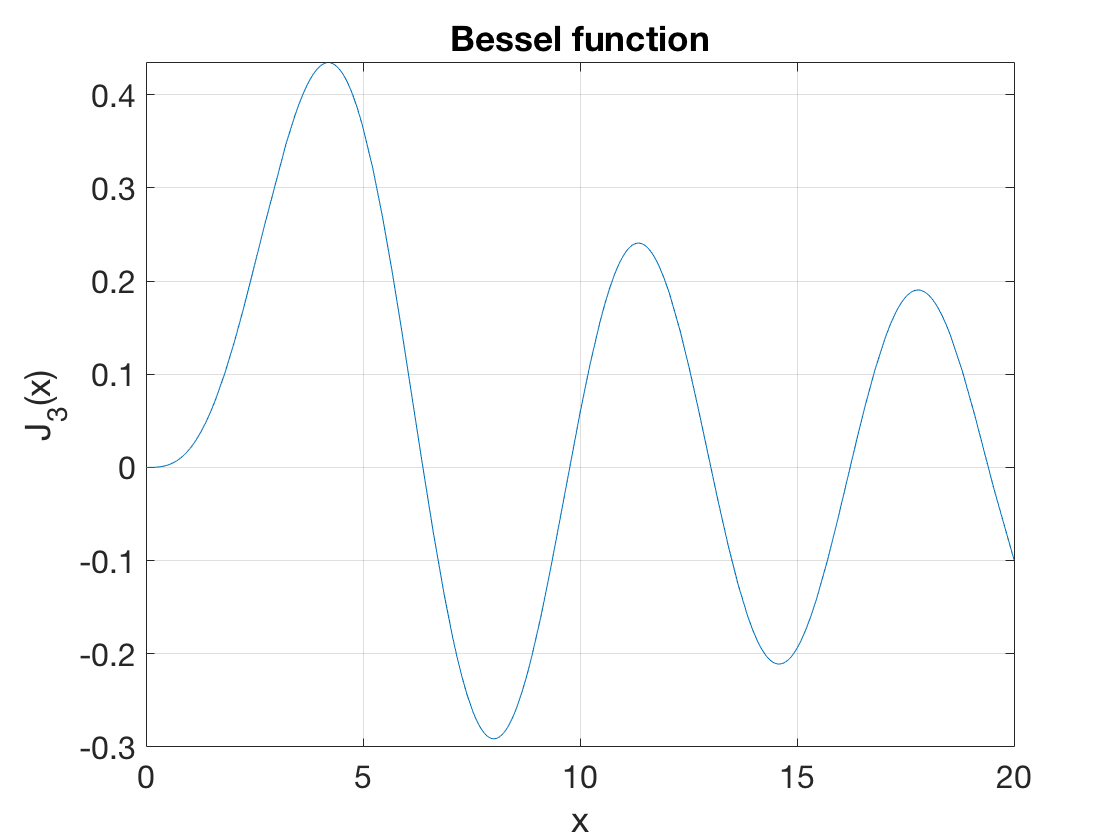

J3 = @(x) besselj(3,x);
fplot(J3,[0 20]), grid on
xlabel('x'), ylabel('J_3(x)')    % ignore this line
title('Bessel function')     % ignore this line

From the graph we see roots near 6, 10, 13, 16, and 19. We use `fzero` to find these roots accurately.

omega = [];
for guess = [6,10,13,16,19]
    omega = [omega;fzero(J3,guess)];
end
omega

omega =    6.3802e+00
   9.7610e+00
   1.3015e+01
   1.6223e+01
   1.9409e+01


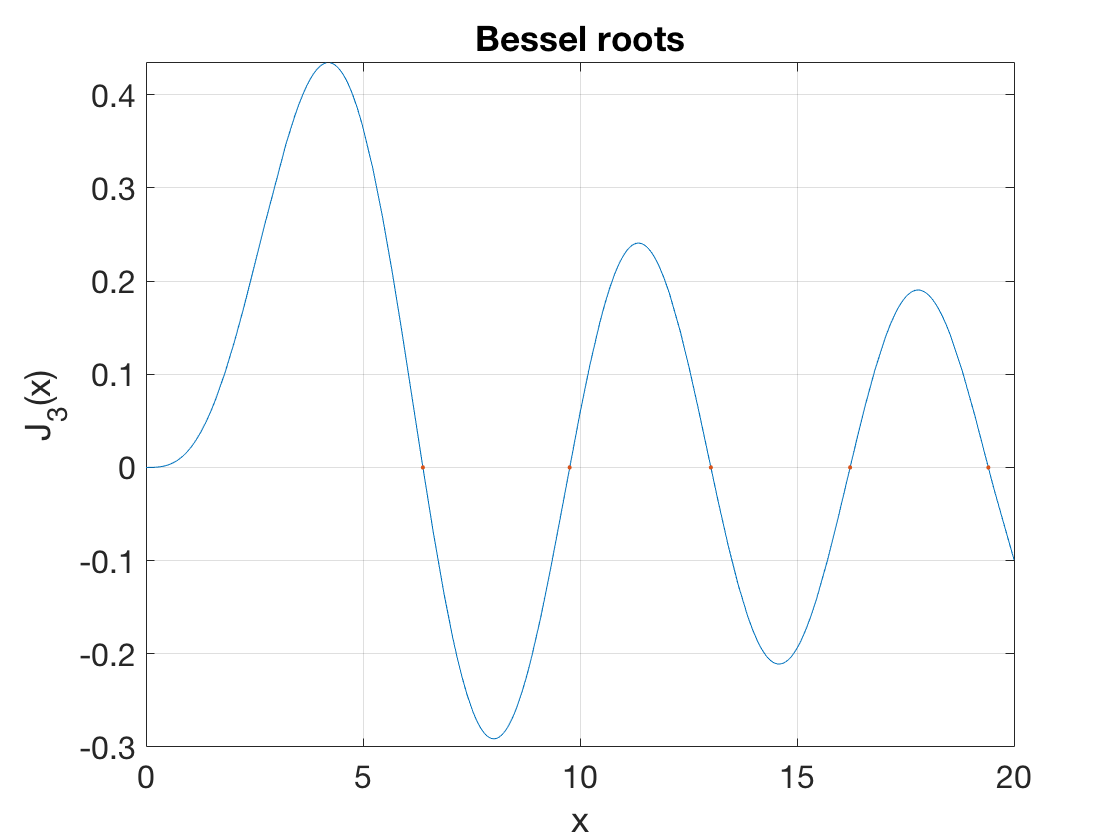

hold on, plot(omega,J3(omega),'.')
title('Bessel roots')    % ignore this line